# Example 3: Implementation of the quad-coherence

 In the example 3, The imaginary part of the coherence is accounted for in the simulation of turbulent velocities.

## Set sampling frequency and record duration

clearvars;close all;clc;

fs = 8; % sampling frequency (in Hertz)
M = 16; % M is the power of 2: If M = 10, 2^M = 1024 time step
[t,f] = getSamplingPara(M,fs);

Duration of target time series is 2.28 hours, i.e. 8.19e+03 sec 



N=numel(t); % number of time step (should be equal to 2^M)
Nfreq = numel(f); % number of frequency step (should be equal to 2^(M-1))
dt = median(diff(t)); % time step (should be equal to 1/fs)



## Set the geometry (a simple grid)

Nyy = 3; % number of nodes along the y axis
Nzz = 3; % number of nodes along the z axis

ymin = -10;
ymax = 10;

zmax = 30 ;
zmin= 30+15;

y = linspace(ymin,ymax,Nyy);
z = linspace(zmin,zmax,Nzz);

[Y,Z] = meshgrid(y,z);

## Set the target mean wind velocity

u_star = 0.8; % Friction velocity (m/s);
kappa = 0.4; % von karman constant
z0 = 0.03; % roughness length;
U = u_star/kappa.*log(Z./z0);


## Set the target wind coherence parameters

The davenport model is used for the sake of simplicity

CohDecay.Cuy = 7; % Arbitrary decay coefficient for u in the "y" direction
CohDecay.Cuz = 10; % Arbitrary decay coefficient for u in the "z" direction
CohDecay.Cvy = 7; % Arbitrary decay coefficient for v in the "y" direction
CohDecay.Cvz = 10; % Arbitrary decay coefficient for v in the "z" direction
CohDecay.Cwy = 6.5; % Arbitrary decay coefficient for w in the "y" direction
CohDecay.Cwz = 3; % Arbitrary decay coefficient for w in the "z" direction


## Set the wind spectral density at each nodes

Su, Sv, Sw and Suw are not normalized here! They are expressed as [Nm x N] matrices where Nm = Nz x Ny.

[Su,Sv,Sw,Suw,~] = KaimalModel(U,Z,f,u_star);


## Run the function windSimFast

The PSDs of the velocity are calculated outside the function windSimFast, whereas the coherence is calculated inside the function windSimFast to keep a balance between robustness and code performance. 


tic
rng(1)
[u,~,~,nodes] = windSimFast(U,f,Su,Sv,Sw,CohDecay,Y,Z,'Suw',Suw,'quadCoh_Cu',[5 10]); %  Suw is here an option!

Expected computation time: From 6 to 17 seconds 


u = bsxfun(@plus,u,U(:)');
u = reshape(u,N,Nzz,Nyy); % whos u1
toc

Elapsed time is 5.768837 seconds.



tic
rng(1) % same rng as previous case
[u1,~,~,nodes] = windSimFast(U,f,Su,Sv,Sw,CohDecay,Y,Z,'Suw',Suw,'quadCoh_Cu',[]); %  Suw is here an option!

Expected computation time: From 8 to 21 seconds 


u1 = bsxfun(@plus,u1,U(:)');
u1 = reshape(u1,N,Nzz,Nyy); % whos u1
toc

Elapsed time is 3.396341 seconds.


## Time series overview

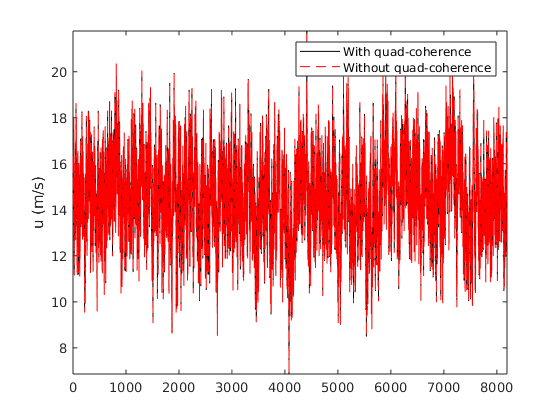

clf;close all;
figure
plot(t,squeeze(u(:,1,1)),'k',t,squeeze(u1(:,1,1)),'r--')
ylabel('u (m/s)')
axis tight
legend('With quad-coherence','Without quad-coherence')

## Co-Coherence and quad-coherence estimation (vertical separations)

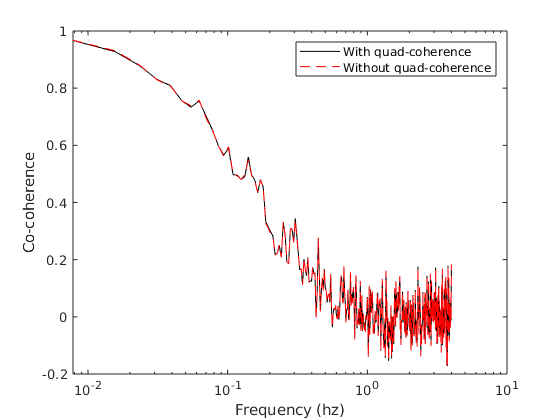

[cocoh, Quad, freq] = coherence(squeeze(u(:,2,1)),squeeze(u(:,1,1)),1024,512,1024,fs);
[cocoh1, Quad1, freq1] = coherence(squeeze(u1(:,2,1)),squeeze(u1(:,1,1)),1024,512,1024,fs);

clf;close all
figure
semilogx(freq,cocoh,'k')
hold on
plot(freq,cocoh1,'r--')
legend('With quad-coherence','Without quad-coherence')
xlabel('Frequency (hz)')
ylabel('Co-coherence')

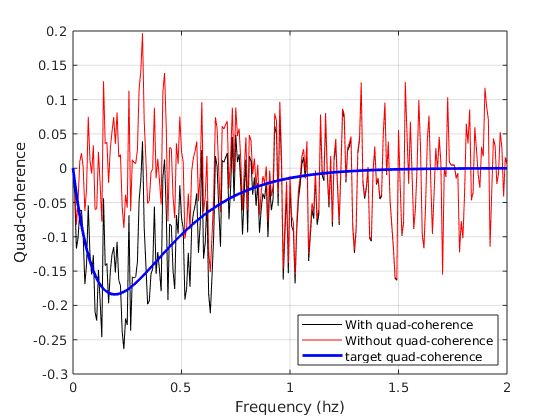



figure
plot(freq1,Quad,'k')
hold on
plot(freq1,Quad1,'r')

fr = freq1.*abs([Z(2,1)-Z(1,1)])./mean([U(2,1) U(1,1)]);
Qu = -(5.*fr).*exp(-10.*fr); % model used in this example


plot(freq1,Qu,'b','linewidth',2)
xlabel('Frequency (hz)')
ylabel('Quad-coherence')
legend('With quad-coherence','Without quad-coherence','target quad-coherence','location','best')
grid on
xlim([0,2])

## Co-Coherence and quad-coherence estimation (lateral separations)

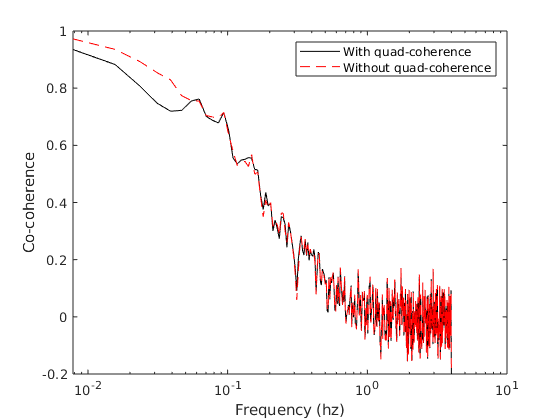

[cocoh, Quad, freq] = coherence(squeeze(u(:,1,2)),squeeze(u(:,1,1)),1024,512,1024,fs);
[cocoh1, Quad1, freq1] = coherence(squeeze(u1(:,1,2)),squeeze(u1(:,1,1)),1024,512,1024,fs);

clf;close all
figure
semilogx(freq,cocoh,'k')
hold on
plot(freq,cocoh1,'r--')
legend('With quad-coherence','Without quad-coherence')
xlabel('Frequency (hz)')
ylabel('Co-coherence')

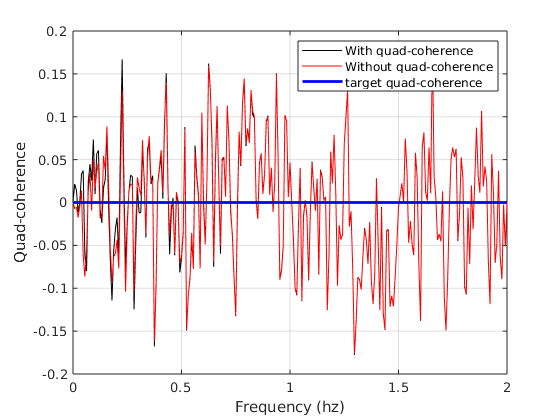



figure
plot(freq1,Quad,'k')
hold on
plot(freq1,Quad1,'r')

fr = freq1.*abs([Z(1,2)-Z(1,1)])./mean([U(2,1) U(1,1)]);
Qu = -(5.*fr).*exp(-10.*fr); % model used in this example


plot(freq1,Qu,'b','linewidth',2)
xlabel('Frequency (hz)')
ylabel('Quad-coherence')
legend('With quad-coherence','Without quad-coherence','target quad-coherence','location','best')
grid on
xlim([0,2])